# Introduction To Cellinoid for Lightcurve Version

Whole Process To show the inversion methond based on cellinoid shape model for lightcurves, observed in various geometries. 

## Difference of Lebedev Quadrature and Triangularization

-     1. Calculating the surface area of Cellinoid Shape model

-     2. Calculating the synthetic lightcurves of Cellinoid Shape model by Triangularization and Lebedev

## Forward Process to calculate brightness based on Cellinoid Shape Model

-     1. Lebedev Precalculation for Specified Degree N=590

-     2. Calculate Stable Pole Direction, as well as Mass, Mass Center of Cellinoid

-     3. Calculate The Sun(E0), Earth(E) position vectors with respect to the JDT, Stable Pole direction,etc

-     4. Calculate the synthetic lightcurve By applying Lebedev Quadrature

## Inverse Problem by L-M algorithm

-     1. Levenberg-Marqudt Optimiazation Tools

-     2. Completing Searching Process for non-Prior information

## Example Program for Pre-Publication of MATLAB version

## Difference of Lebedev Quadrature and Triangularization

- Show Lebedev Convex Hull and compare the approximation to Sphere Volume

For Lebedev N=266, Facets Num: 528, Vertex Num: 266


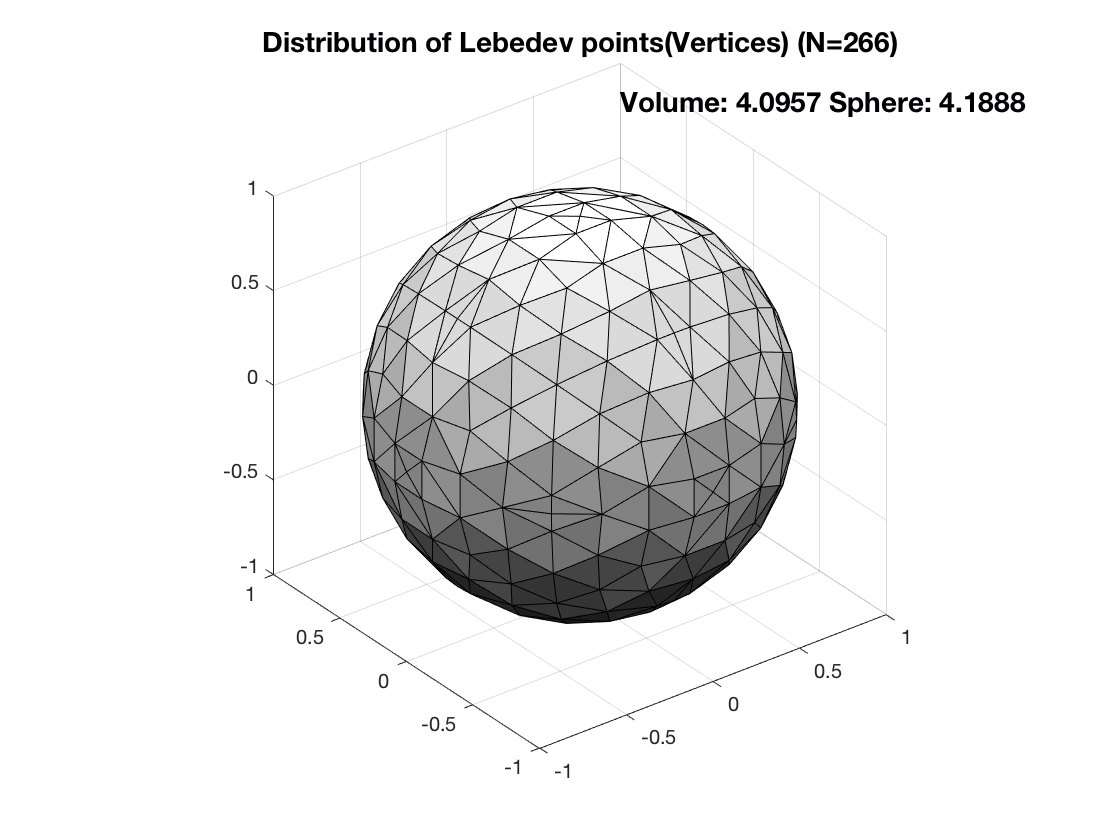

path('./Lebedev',path);
addpath ./Lebedev -END
ShowLebedev(2);

- Show the Comparison based on Ellipsoid Model for Triangularization and Lebedev

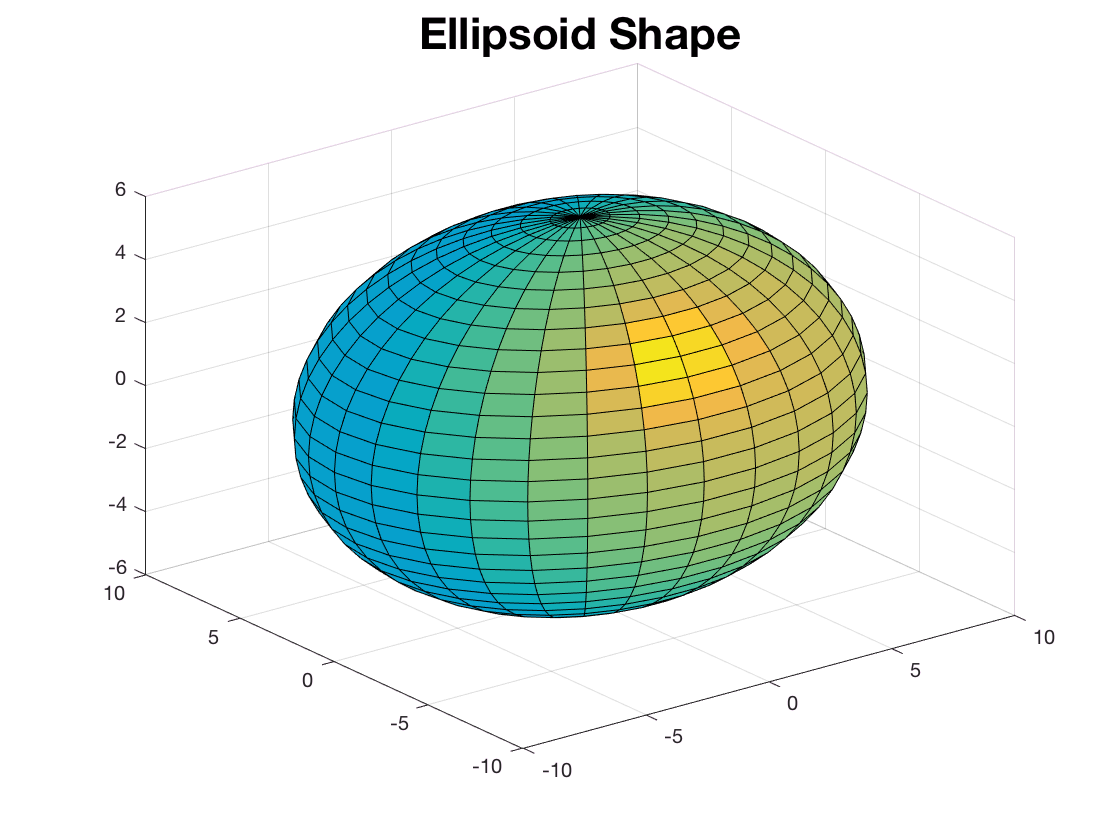

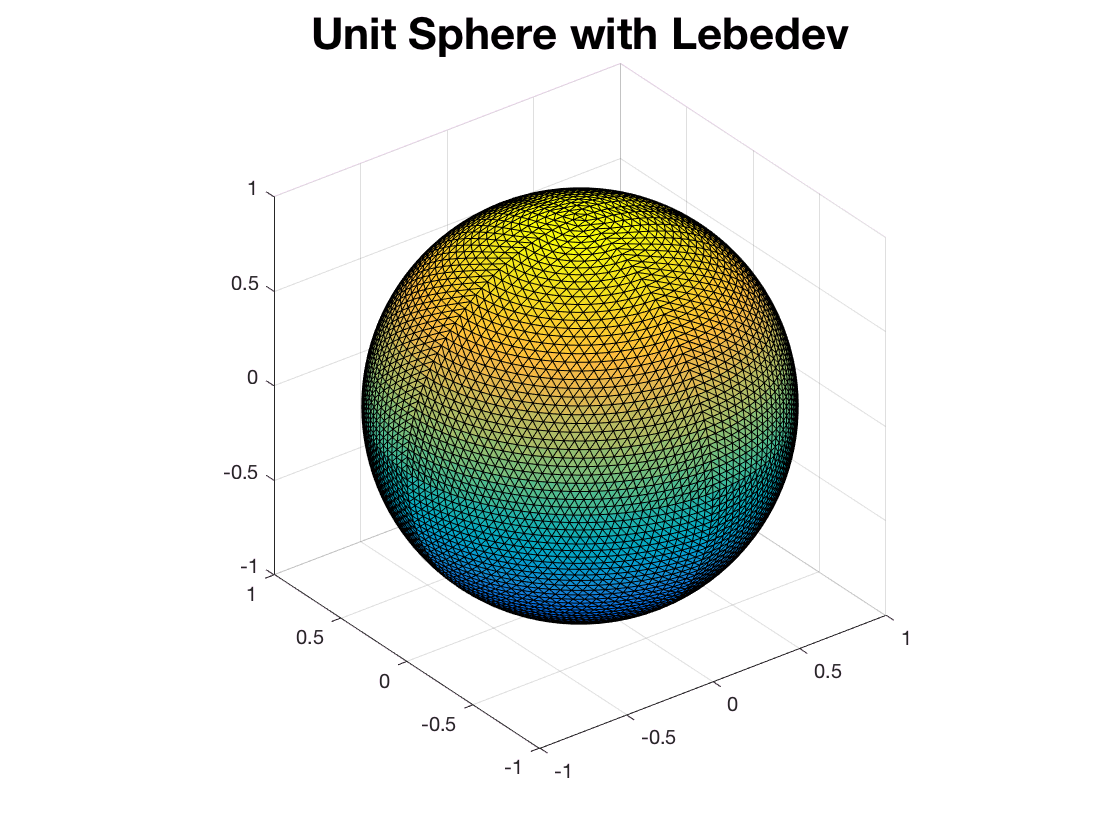

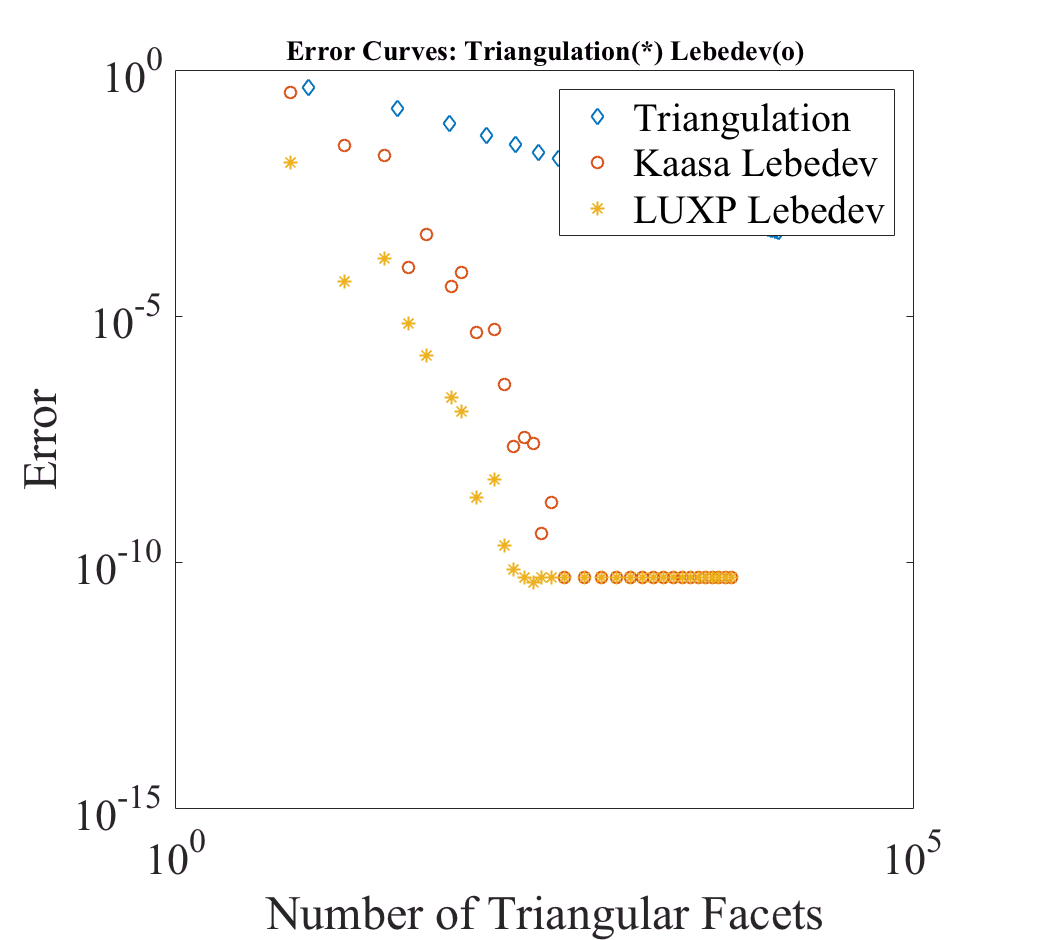

LC_CurvVS(10,8,6);

- For Cellinoid, Compare the Triangularization and Lebedev by 

1. Calculating the surface area of Cellinoid Shape model

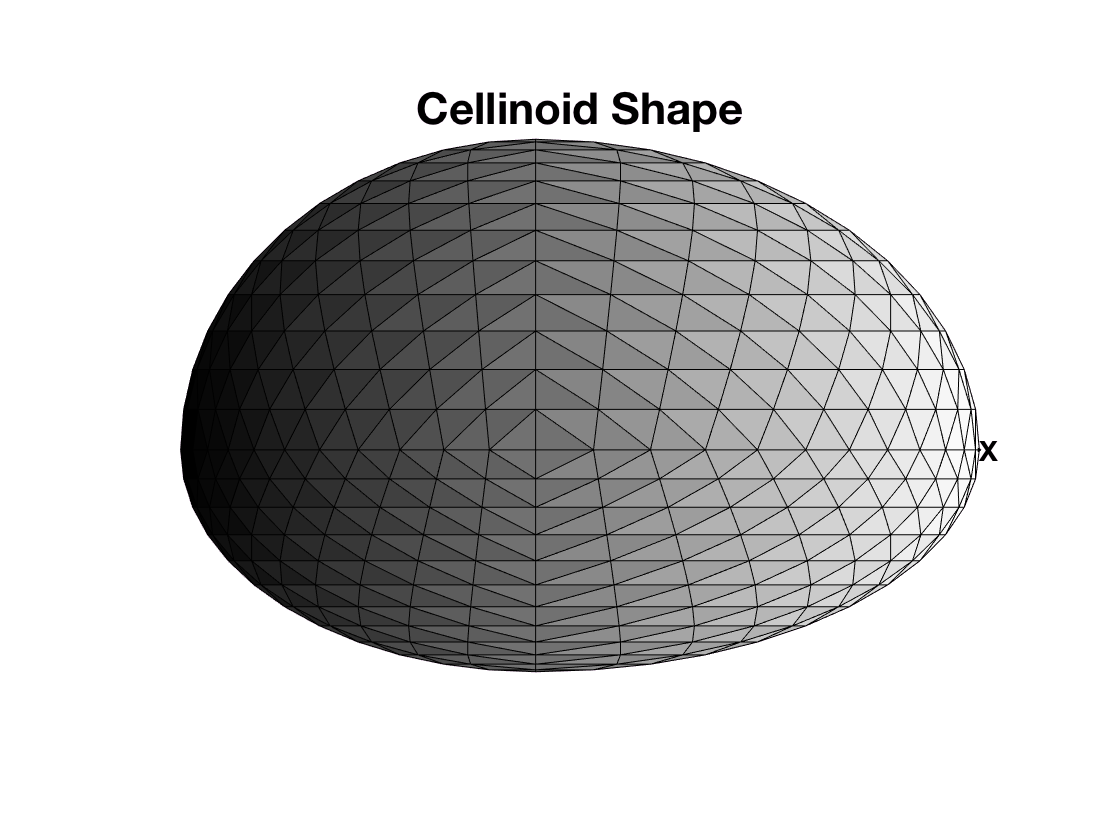

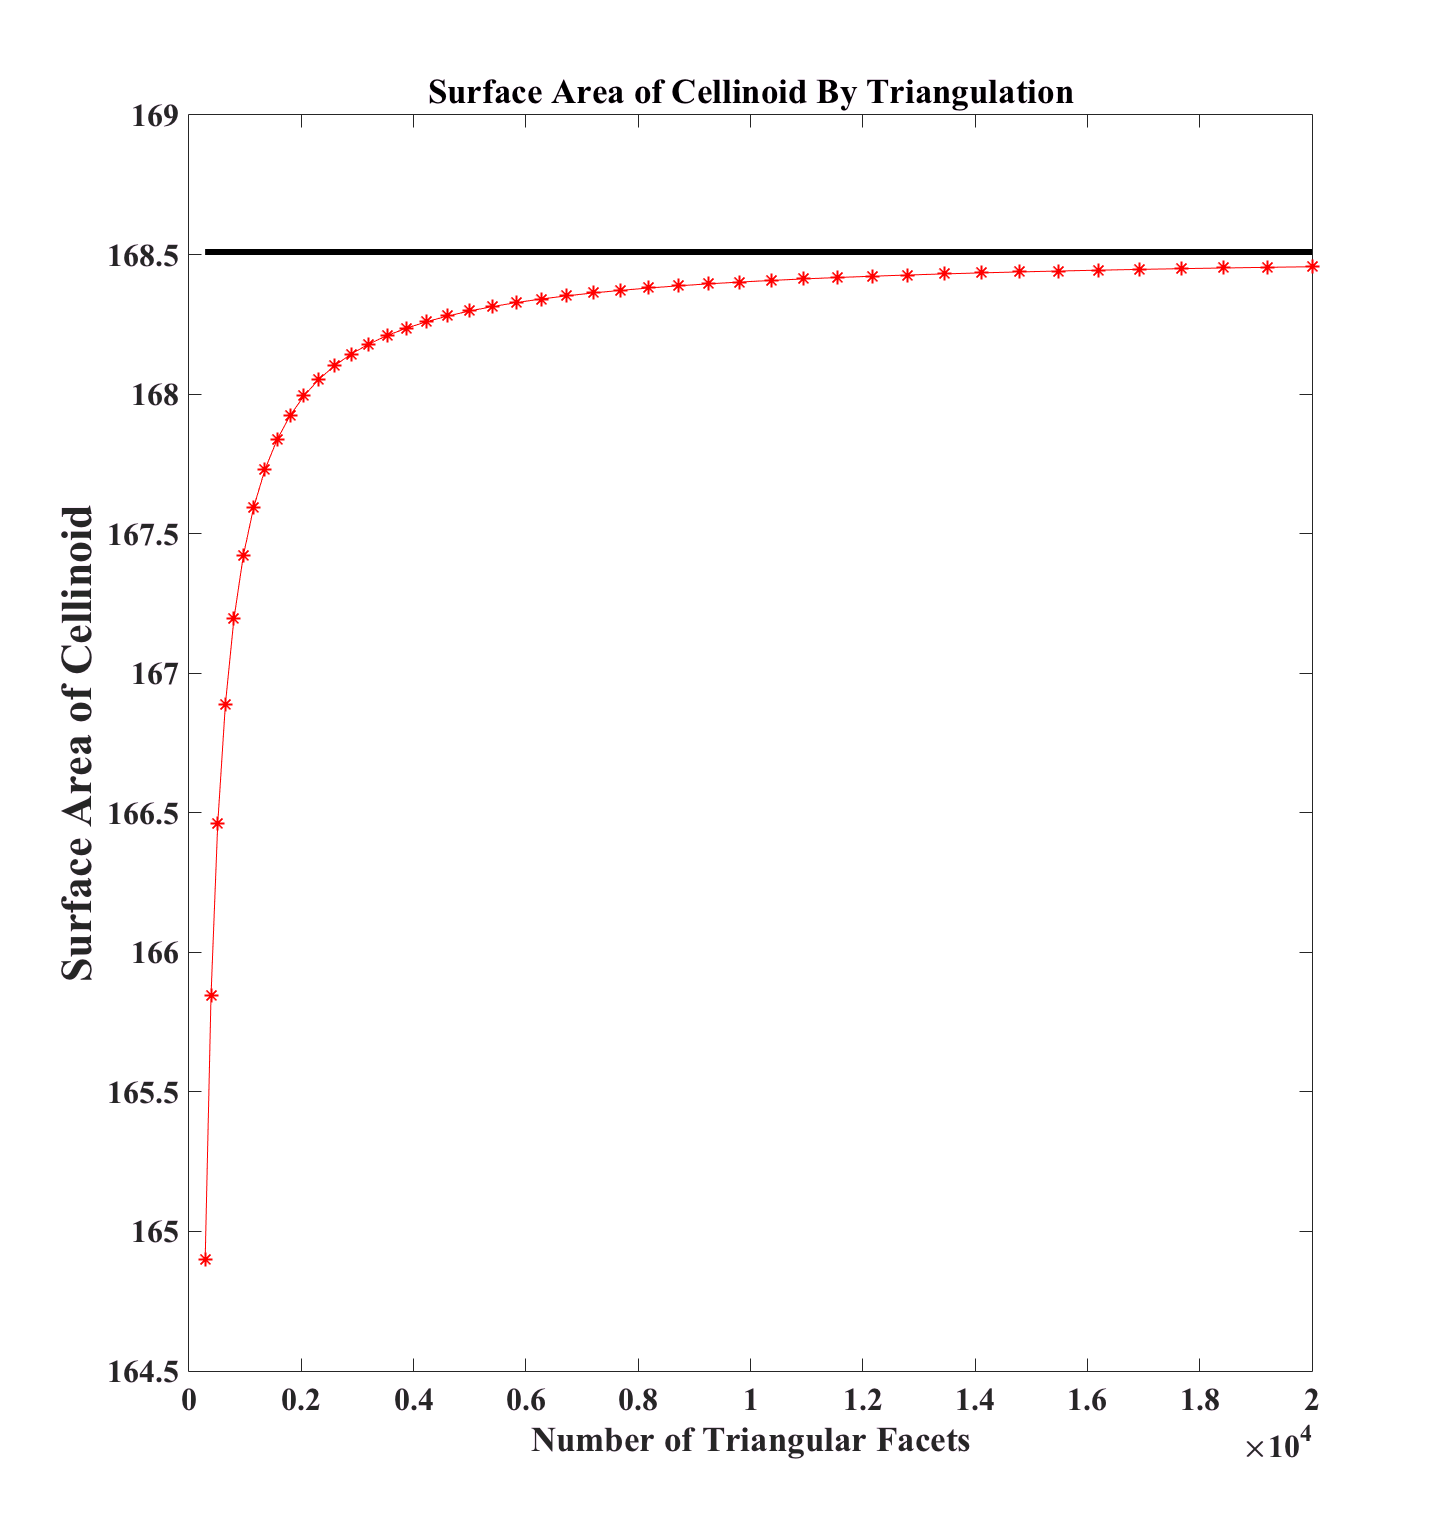

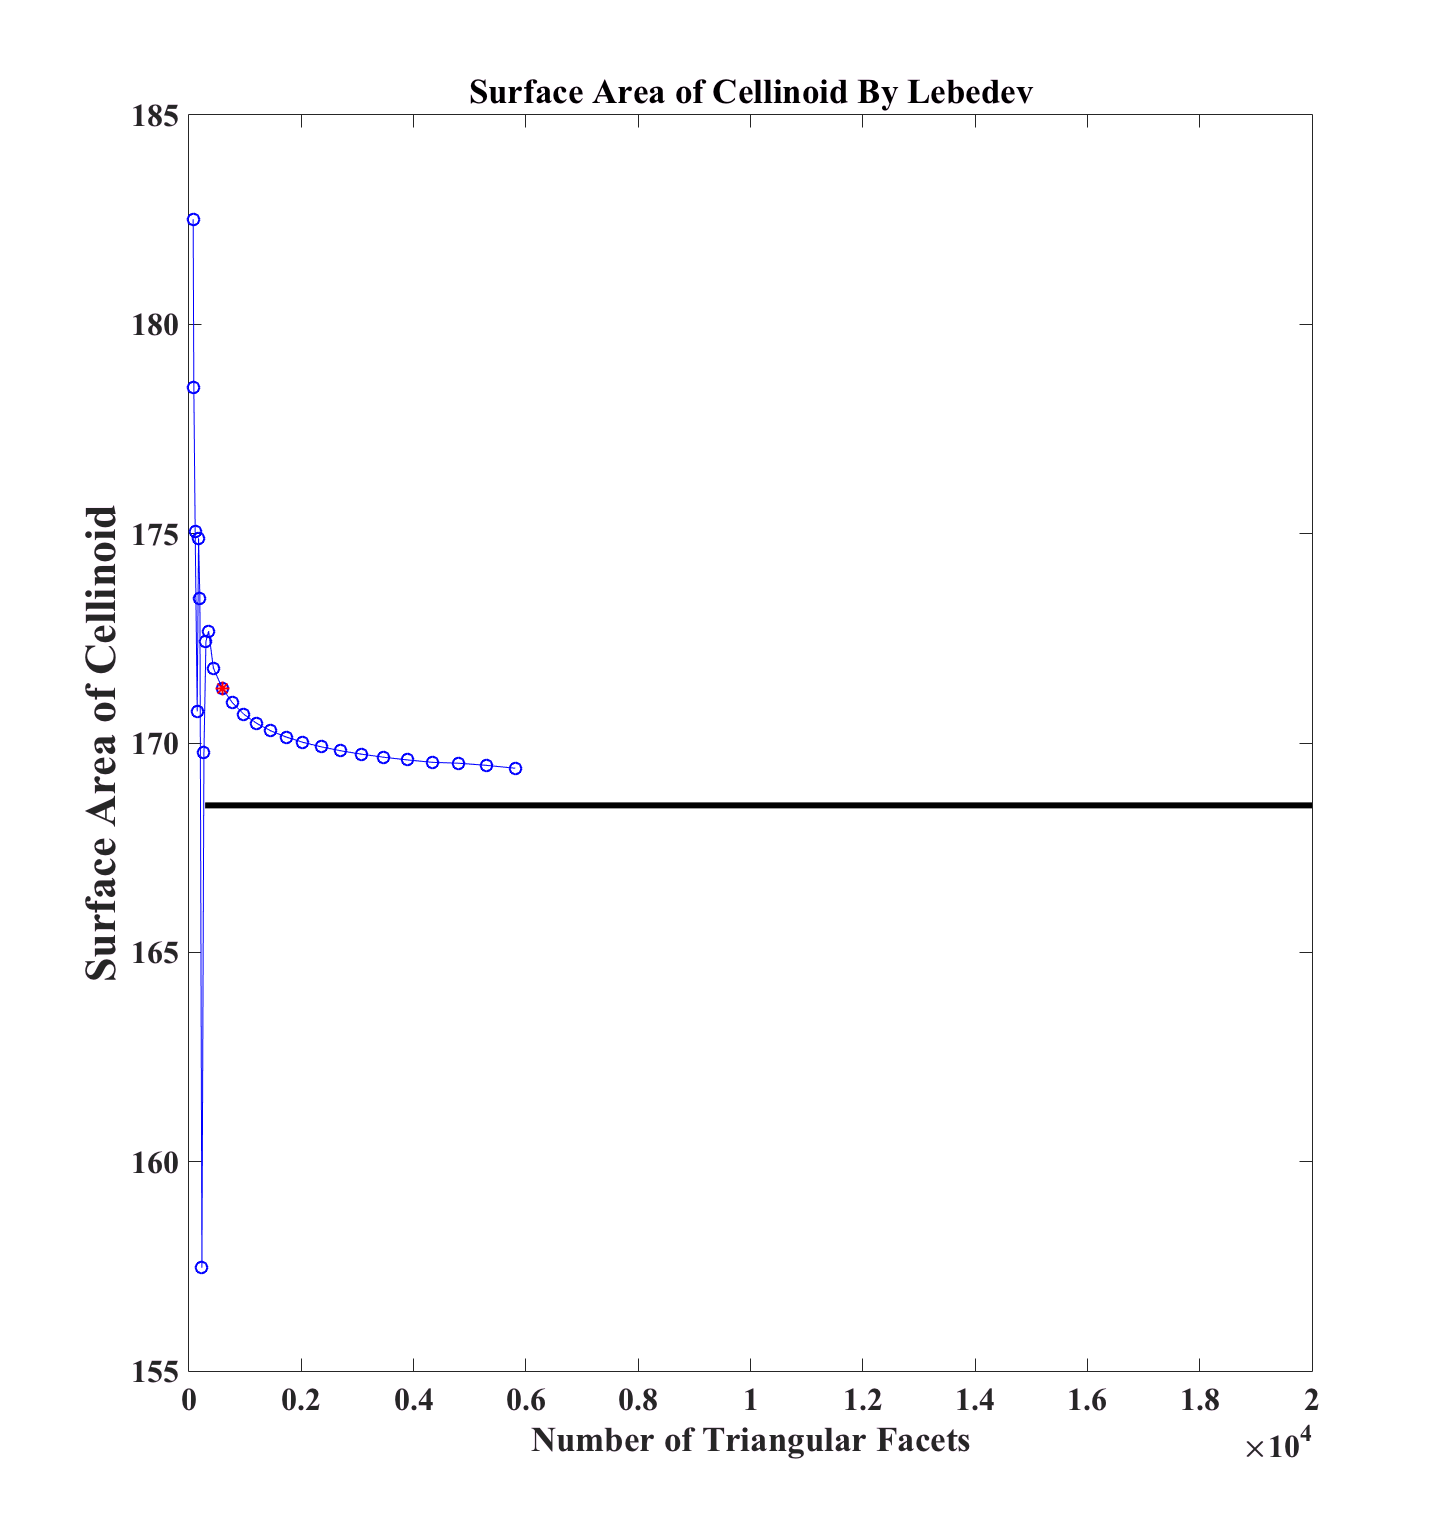

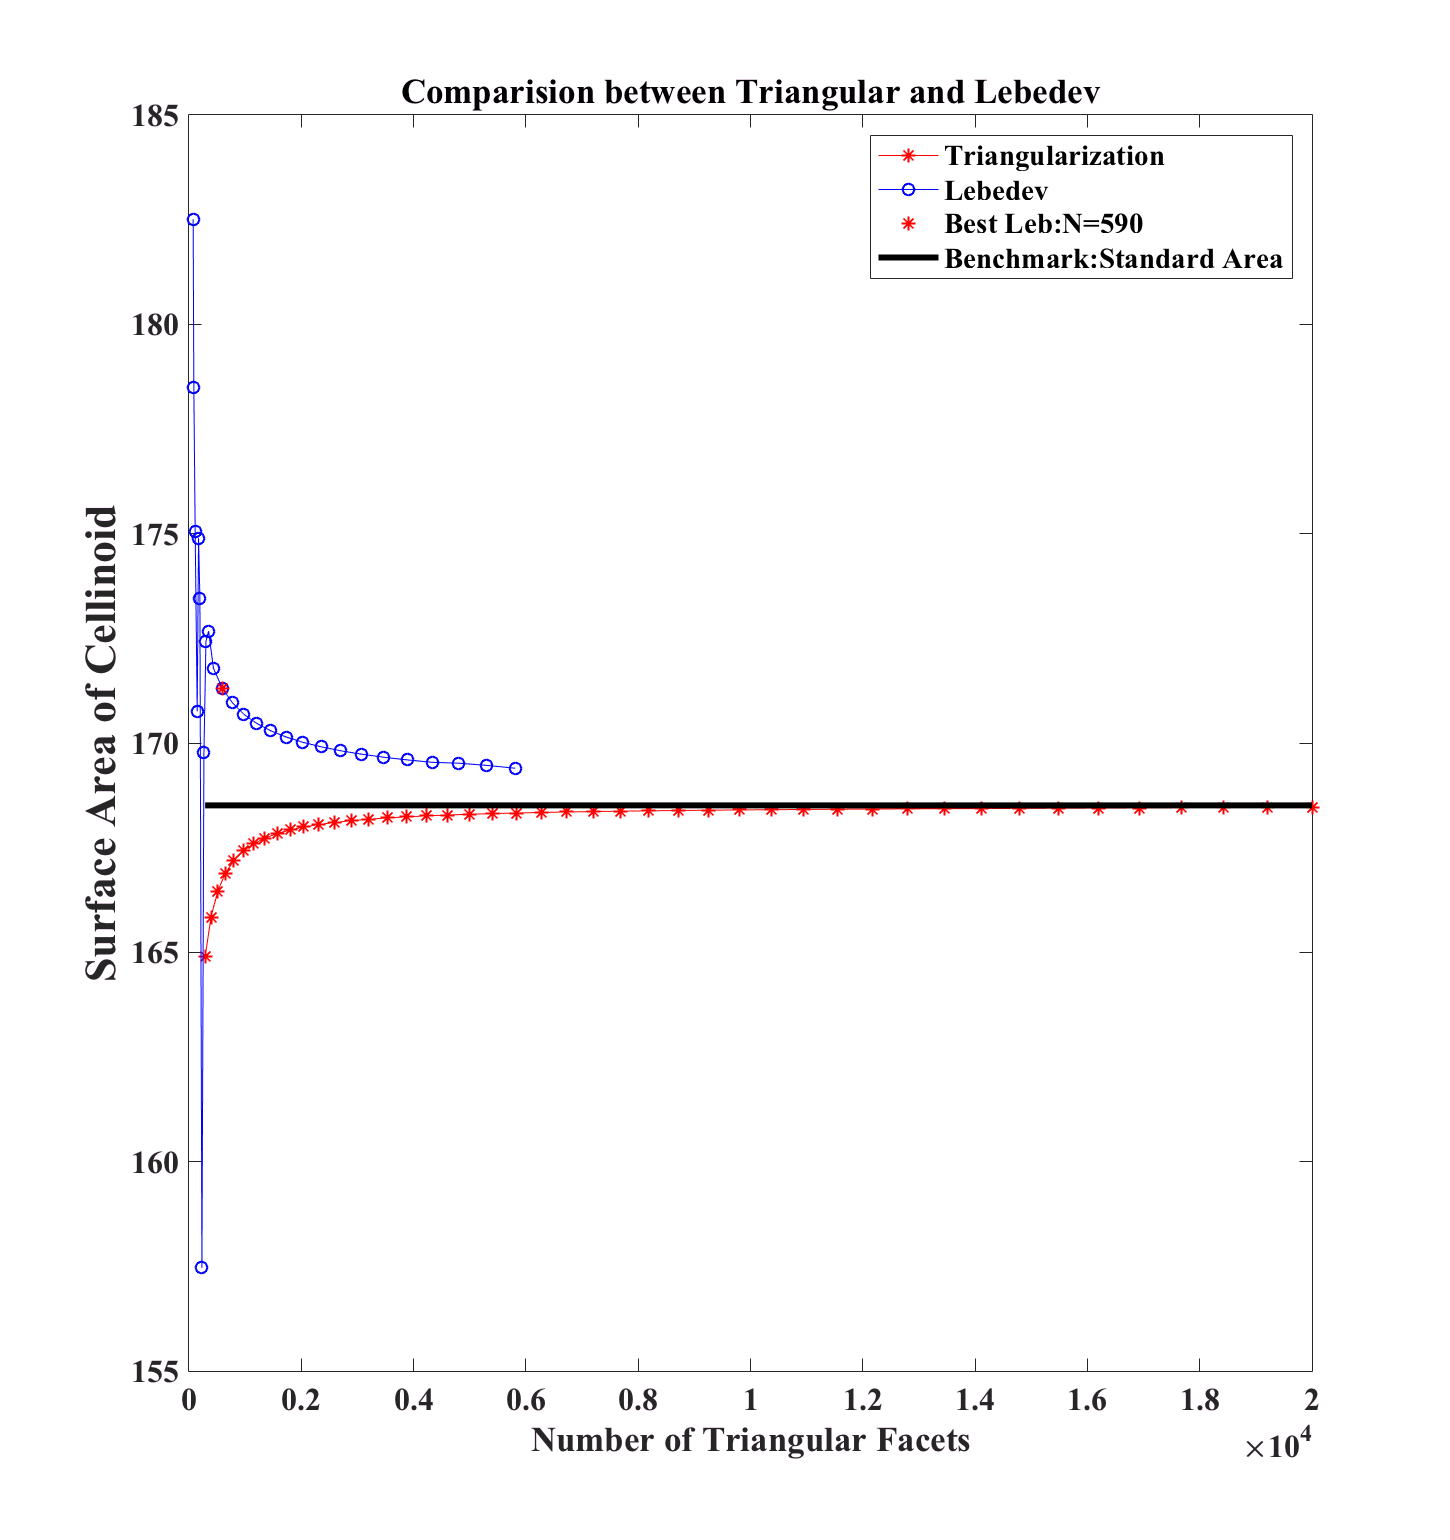

CMP_Leb_Tri;

2. Calculating the synthetic lightcurves of Cellinoid Shape model by Triangularization and Lebedev

    Conclusion: Lebedev performces better! accelarate for 20X speed! Best Degree: 590

Time for Triangularization:


TimeLast = 5.6720

Time for Lebedev:


TimeLast = 0.1807

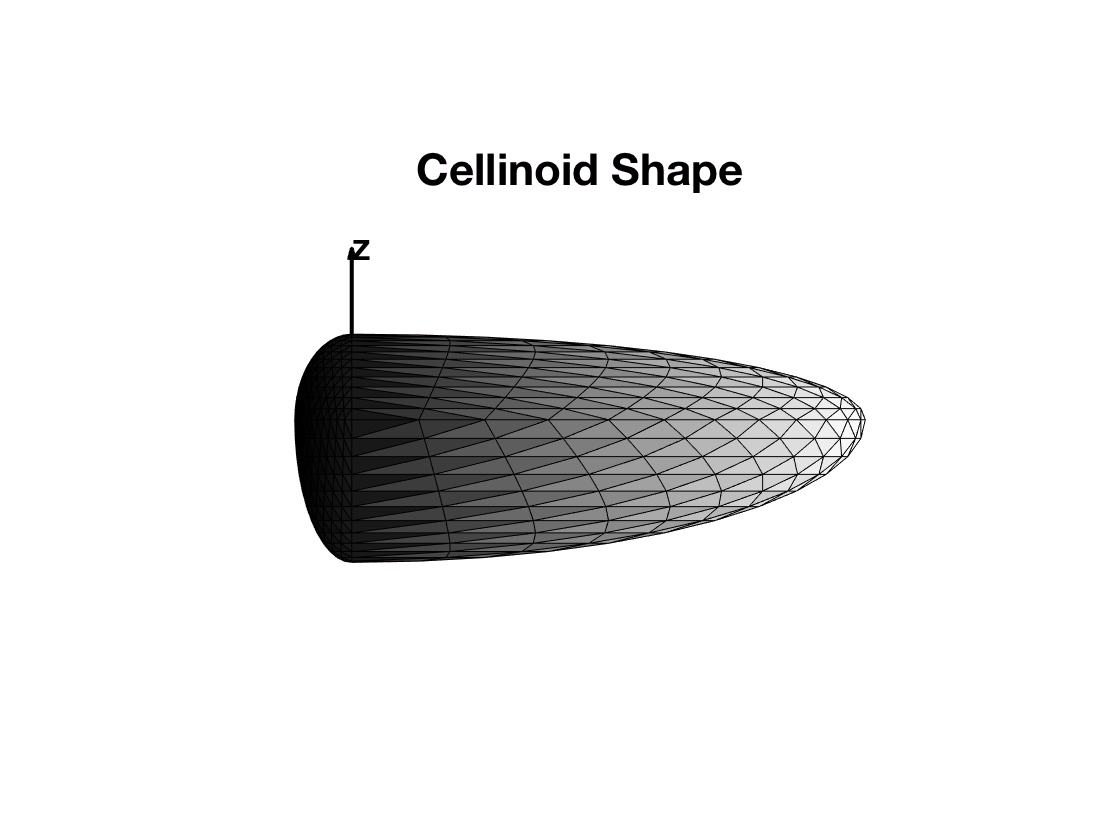

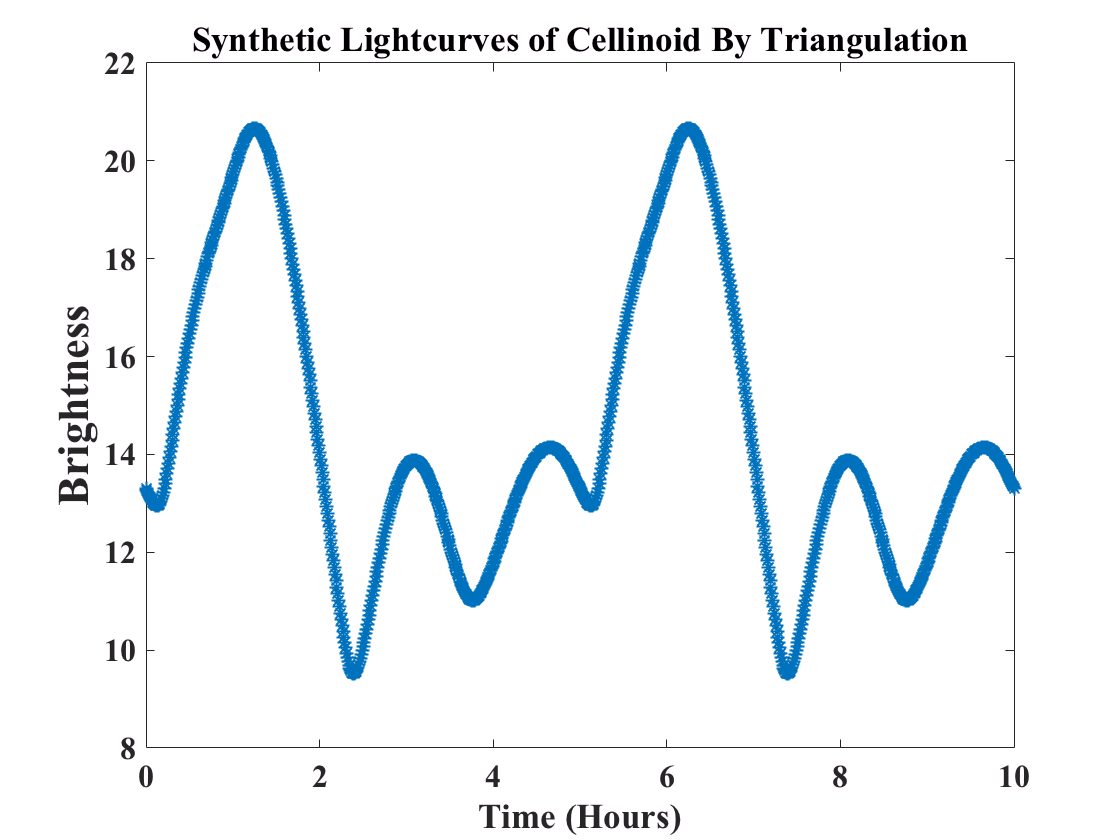

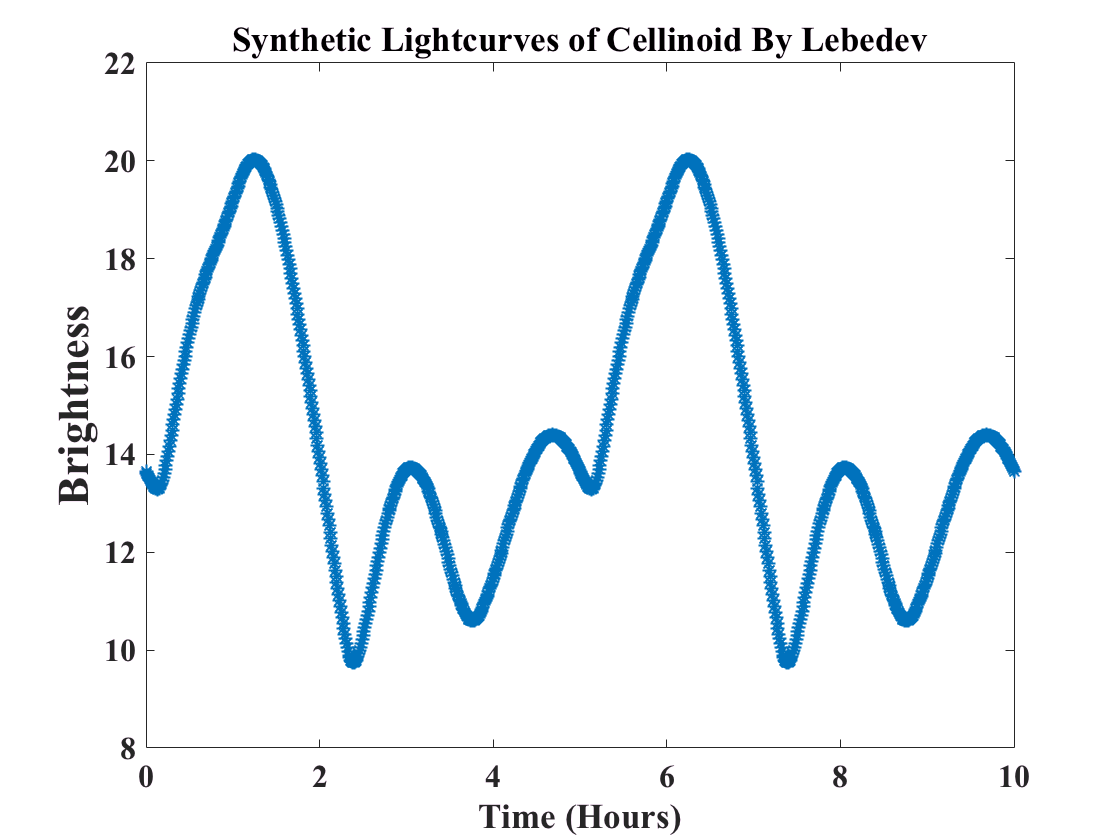

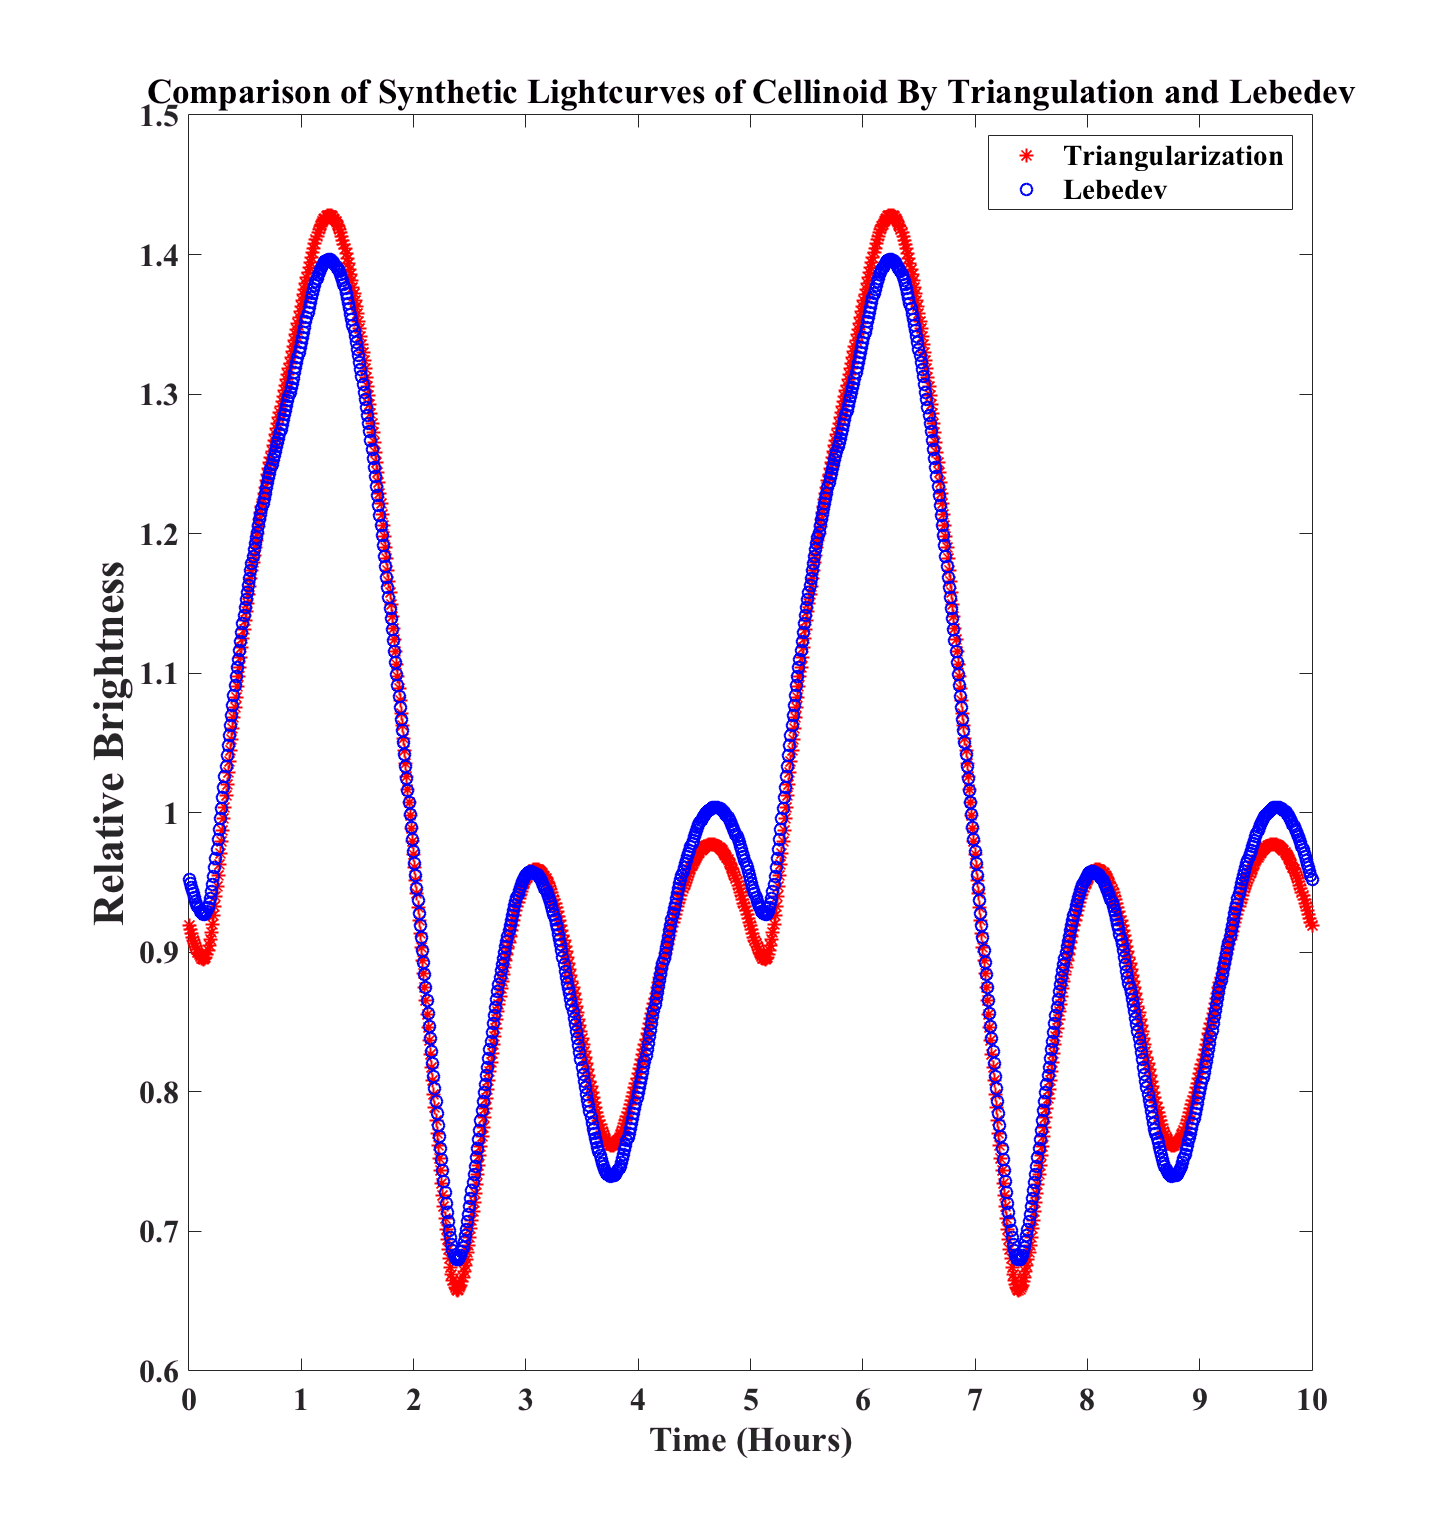

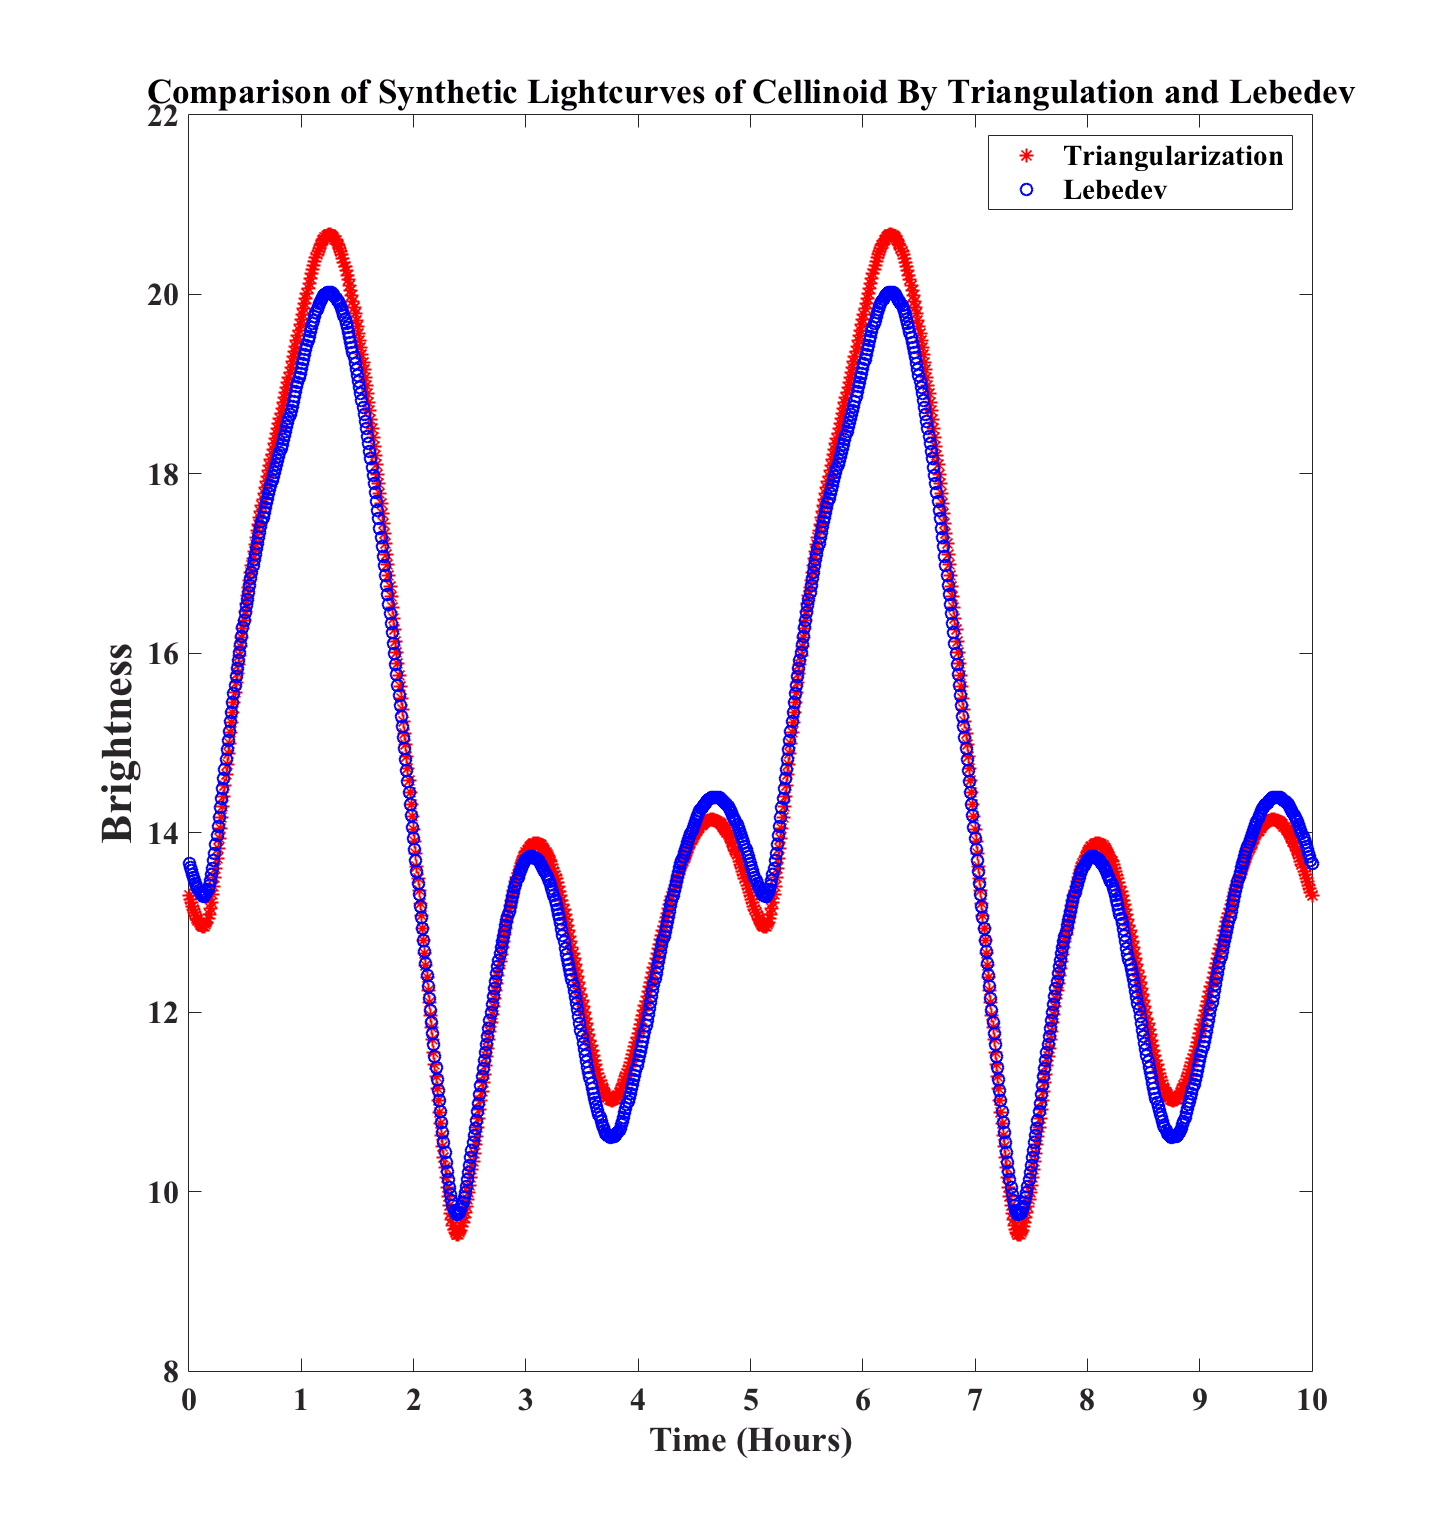

CMP_Leb_Tri_LightCurves;

## Forward Process to Calculate Synthetic Lightcurves based on Cellinoid Shape Model

  1. Lebedev Precalculation for Specified Degree N=590. 

    Generate a data file with the matrix to record the Lebedev data for the specified Degree N (e.g.: 590,5810). 

        Format: LebData = [x,y,z,index], xyz is the unit normal vector, distributed in unit sphere, while index =1-8 is the octant number for this normal vector. Furthermore, the xyz are ordered by the index from 1 to 8.  And it also generates a index data for quickly visiting the normal vectors in each octant.  For all vectors in i-th octant:    Matlab code: if i ==1 VecInd = 1:LebInd(i); else VecInd = (LebInd(i-1)+1):LebInd(i)        

path('./Lebedev',path);N=590;
[LebData, LebInd] = GetLebData(N);

    Calculate Normal Vector and area of small facets for Lebedev methods by applying LUXP Curvature Function:

cg  = [1, 0.9, 0.75, 0.75, 0.5, 0.5, 100, 50, 5, 120, -0.4, 1, 0.10]'; 
[NormalVec, G, w] = CalNormalVector(LebData, LebInd, cg); 

2. Calculate Stable Pole Direction, as well as Mass, Mass Center of Cellinoid

    Default settings: only get stable pole direction, the code for other parameters are commented! V is the three new axes of the coordinate system under the assumption that the Z-axis is the stable pole direction. D is the corresponding moments of the inertia.

[V,D] = StablePole(cg);

3. Calculate The Sun(E0), Earth(E) position vectors at asteroid-centric coordinate system, with respect to the JDT, Stable Pole direction,etc. The Juliandate and E0,E in ecliptic frame will be provied in the built-in functin: fReadData.m

[E0, E, JDT, LCm] = GetSunEarth(cg);

Undefined function or variable 'E0'.


 4. Calculate the synthetic lightcurve By applying Lebedev Quadrature

         cg:= [six axes, lam,beta of pole, period and intial Phase, three scattering factors] total 10+3 = 13 parameters

SynLC = CalSynLC(cg);

## Inverse Problem by L-M algorithm

1. Levenberg-Marqudt Optimiazation Tools

Apply the locally optimization tool: Levenberg-Marqudt algorithm to search the best-fit solution with the given initial test values: cg

global JDT  E0 E  BRT LCm
[LC, LCm] = fReadData;
JDT = LC(:,1); BRT= LC(:,2); E0 = LC(:, 3:5)'; E = LC(:, 6:8)';  
cg0 = [1, 0.9, 0.75, 0.75, 0.5, 0.5, 100, 50, 5, 120]';cg0 = cgModify(cg0, 'M');
UpdateIndex = ones(10,1); UpdateIndex(1) = 0;
cg_bestfit = LM_Inverse(cg0, UpdateIndex);

2. Completed Searching Process for non-Prior information

- (1) Search the **global** best-fit **period** based on LM inverse 

cg_bestfit_global = SearchProcess;

**The best way** is to accelerate by the parallel toolbox in MATLAB. i.e. parfor. After setting the search interval and accuracy in the parfor_SearchPrd file, then run it and wait for finishing all the search. The results of best-fit cg and Chisq will be recorded in OUTPUT/Prd_date_interval.mat files. Then edit and run AnalyPrd.m file to derive the best period.

parfor_SearchPrd
AnalyPrd

        Notice:

        1. change the deltaPrd in parfor_SearchPrd and the searching scheme for period. Then Run it to collect the best fit cg with the corresponding chisquare

       2. The best search period scheme maybe: 

                A. Fix the pole orientation to (0, 90), i.e. Z-axies of asteorid default coordinate system; 

                B. Fix semi-axes to [1, 1, 0.8, 0.8, 0.6, 0.6], i.e. Ellipsoid. This case for the large data set and the good lightcurves morphology situations. 

        Then Set UpdateIndex to all 0, excep for Period and Initial Phase. This scheme will save much computational time and the search result will be good, especially in the case of Setting DeltaPrd = 0.001.

        3. Derive the best-fit period and the corresponding intial phase angle by AnalyPrd.m after changing its default folder, storing the searching results mat files.

        4.  For Bad Situations, run parfor_SearchPrdRefine to search the period with a more refined DeltaPrd to try to get the best-fit period. *Same code as the parfor_SearchPrd, only for a further modification use.*

- (2) Search the **global** best-fit **Pole** based on LM inverse and the derived best-fit period and initial phase

parfor_SearchPole
AnalyPole